# Loading Dataset

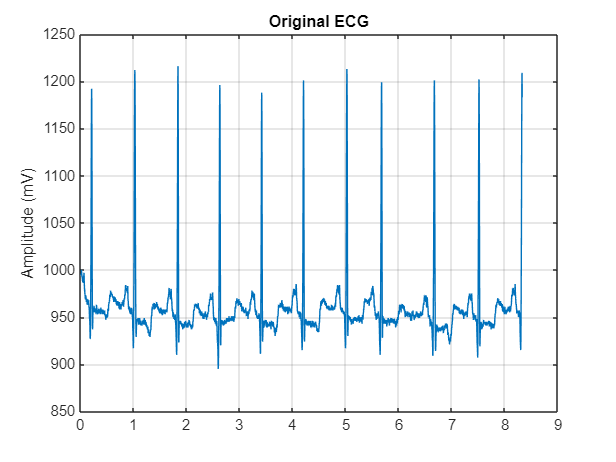

clc;
clear;
close all;

data = readmatrix('100.csv');
x = data(:,2);
x = x(:);
N = length(x);

fs = 360;
t = (0:N-1)/fs;

figure;
plot(t(1:3000), x(1:3000))
title('Original ECG')
ylabel('Amplitude (mV)')
grid on

# Adding WGN(White Gaussian Noise)

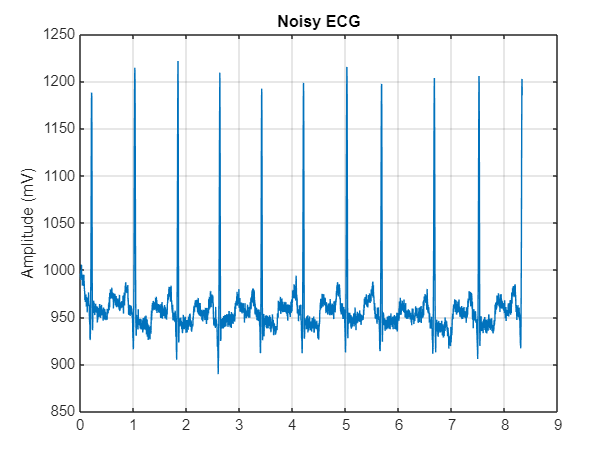

x_mean = mean(x);
noise = 0.1 * std(x) * randn(size(x));
x_noisy = (x - x_mean) + noise;

figure;
plot(t(1:3000), x_noisy(1:3000) + x_mean)
title('Noisy ECG')
ylabel('Amplitude (mV)')
grid on

# Decomposition

phi = [0.5 1 0.5];
psi = [1 0 -1];
phi = phi / norm(phi);
psi = psi / norm(psi);
L = length(phi);

levels = 3;
x_level = x_noisy;

cA = cell(levels,1);
cD = cell(levels,1);

for i = 1:levels
    len = length(x_level);
    tempA = zeros(len,1);
    tempD = zeros(len,1);

    for k = 1:len
        for n = 1:L
            idx = k + n - 1;
            if idx <= len
                tempA(k) = tempA(k) + x_level(idx)*phi(n);
                tempD(k) = tempD(k) + x_level(idx)*psi(n);
            end
        end
    end

    cA{i} = tempA(1:2:end);
    cD{i} = tempD(1:2:end);
    x_level = cA{i};
end

# Thresholding

for i = 1:levels
    sigma = median(abs(cD{i})) / 0.6745;
    lambda = sigma * sqrt(2*log(length(cD{i})));
    cD{i} = sign(cD{i}) .* max(abs(cD{i}) - lambda, 0);
end

# Reconstruction

for i = levels:-1:1
    len = length(cA{i});
    x_rec = zeros(len*2,1);

    for k = 1:len
        for n = 1:L
            idx = 2*k + n - 2;
            if idx <= length(x_rec)
                x_rec(idx) = x_rec(idx) + cA{i}(k)*phi(n) + cD{i}(k)*psi(n);
            end
        end
    end

    cA{i} = x_rec;
end

x_denoised = x_rec(1:N);% + x_mean;

x_norm = x_denoised / max(abs(x_denoised));



# Plotting

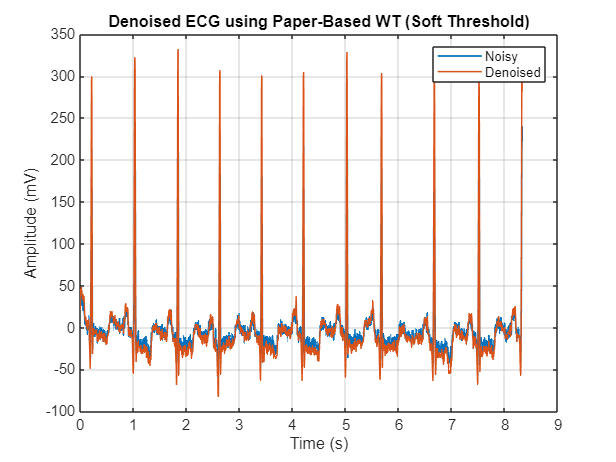

figure;
plot(t(1:3000), x_noisy(1:3000),LineWidth=1.2);hold on
plot(t(1:3000), x_denoised(1:3000),LineWidth=1);hold off
legend("Noisy","Denoised")
title('Denoised ECG using Paper-Based WT (Soft Threshold)')
xlabel('Time (s)')
ylabel('Amplitude (mV)')
grid on

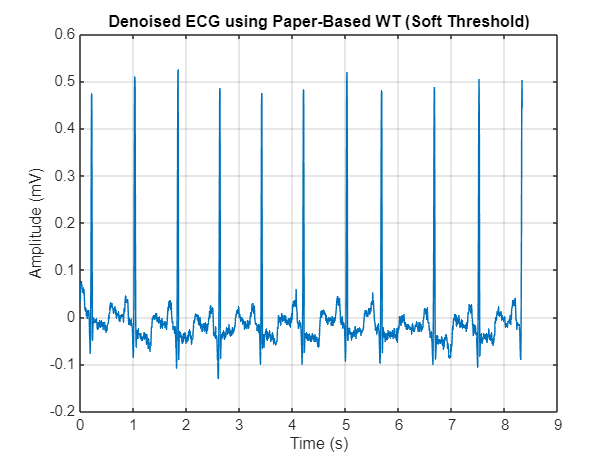


figure;
plot(t(1:3000), x_norm(1:3000),LineWidth=1)
title('Denoised ECG using Paper-Based WT (Soft Threshold)')
xlabel('Time (s)')
ylabel('Amplitude (mV)')
grid on